i=5;
j=10;
i_zoom = 7;
j_zoom = 10;

SNR=-25:5:30;
figure_size = [100, 100, 700, 400]; % [left, bottom, width, height]
lineWidth=1.5;
label_fontSize = 14;
% specify color
cLS_LI = "#0072BD";
cLS_CNN = "#D95319" ;
cLS_LI_CNN = "#EDB120";
cLS_GAN = "#77AC30"; 
cLS_LI_GAN =  "#7E2F8E";

# In source domain

data_GAN = load('../model/static/GAN/BS16/3500_3516/ver11_/nmse.mat');
data_CNN_0_30 = load('../figure/static/CNN/BS16/3500_3516/ver14_/NMSE.mat');
data_CNN_25_5 = load('../figure/static/CNN/BS16/3500_3516/ver27_/NMSE.mat');
data_CNN.nmse_LI_NN_val = [data_CNN_25_5.nmse_LI_NN_val, data_CNN_0_30.nmse_LI_NN_val];
data_CNN.nmse_LS_NN_val = [data_CNN_25_5.nmse_LS_NN_val, data_CNN_0_30.nmse_LS_NN_val];

figure;
set(gcf, 'Position', figure_size); % Set the figure size
plot(SNR(i:j), data_GAN.nmse_LS_LI_val(i:j), 'DisplayName', 'LS+LI', 'color', cLS_LI,  'LineWidth', lineWidth);
hold;

Current plot held


plot(SNR(i:j), data_CNN.nmse_LS_NN_val(i:j), 'DisplayName', 'LS+CNN', 'color', cLS_CNN,  'LineWidth', lineWidth);
plot(SNR(i:j), data_CNN.nmse_LI_NN_val(i:j), 'DisplayName', 'LS+LI+CNN', 'color', cLS_LI_CNN,  'LineWidth', lineWidth);
plot(SNR(i:j), data_GAN.nmse_LS_GAN_val(i:j), 'DisplayName', 'LS+GAN', 'color', cLS_GAN,  'LineWidth', lineWidth);
plot(SNR(i:j), data_GAN.nmse_LI_GAN_val(i:j), 'DisplayName', 'LS+LI+GAN', 'color', cLS_LI_GAN,  'LineWidth', lineWidth);
xticks(SNR(i:j));
legend;
xlabel('SNR (dB)', fontsize=label_fontSize);
ylabel('NMSE', fontsize=label_fontSize);


axes('Position', [0.6, 0.4, 0.25, 0.25]);
x_zoom = SNR(i_zoom:j_zoom);

hold;

Current plot held


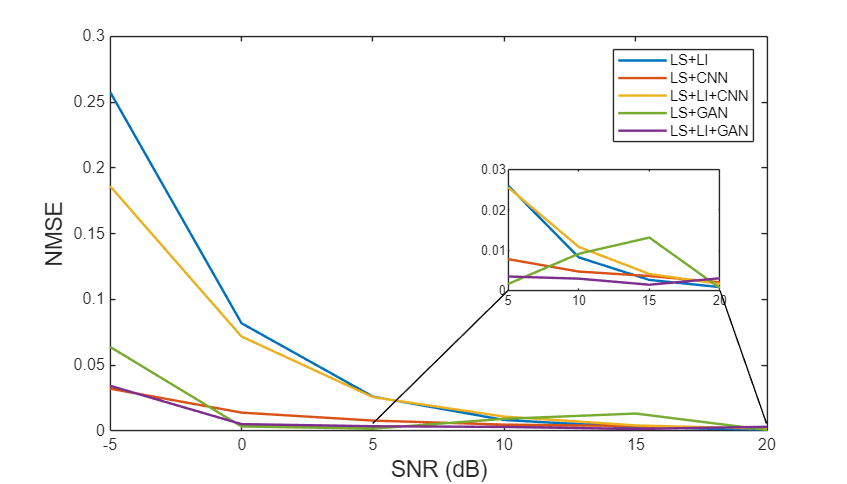

box on;
% Plot the zoomed-in data in the inset
plot(SNR(i_zoom:j_zoom), data_GAN.nmse_LS_LI_val(i_zoom:j_zoom), 'DisplayName', 'LS+LI', 'color', cLS_LI,  'LineWidth', lineWidth);

plot(SNR(i_zoom:j_zoom), data_CNN.nmse_LS_NN_val(i_zoom:j_zoom), 'DisplayName', 'LS+CNN', 'color', cLS_CNN,  'LineWidth', lineWidth);
plot(SNR(i_zoom:j_zoom), data_CNN.nmse_LI_NN_val(i_zoom:j_zoom), 'DisplayName', 'LS+LI+CNN', 'color', cLS_LI_CNN,  'LineWidth', lineWidth);
plot(SNR(i_zoom:j_zoom), data_GAN.nmse_LS_GAN_val(i_zoom:j_zoom), 'DisplayName', 'LS+GAN', 'color', cLS_GAN,  'LineWidth', lineWidth);
plot(SNR(i_zoom:j_zoom), data_GAN.nmse_LI_GAN_val(i_zoom:j_zoom), 'DisplayName', 'LS+LI+GAN', 'color', cLS_LI_GAN,  'LineWidth', lineWidth);
annotation('line', [0.44, 0.6], [0.125, 0.4], 'LineWidth', 0.3);
annotation('line', [0.85, 0.905], [0.4, 0.125], 'LineWidth', 0.3);


% xlim([4 6]);  % Set x-axis limits for zoom
% ylim([min([y1_zoom, y2_zoom]) max([y1_zoom, y2_zoom])]);  % Set y-axis limits for zoom


% title('Performance of approaches in source domain')

# In target domain

Without Transfer learning

transfer_GAN = load('../transfer/transferd_model/static/GAN/ver9_/NMSE.mat');
transfer_CNN_0_30 = load('../transfer/transferd_model/static/CNN/ver10_/NMSE.mat');
transfer_CNN_25_5 = load('../transfer/transferd_model/static/CNN/ver11_/NMSE.mat');
transfer_CNN.nmse_LI_NN_val = [transfer_CNN_25_5.nmse_LI_NN_val, transfer_CNN_0_30.nmse_LI_NN_val];
transfer_CNN.nmse_LS_NN_val = [transfer_CNN_25_5.nmse_LS_NN_val, transfer_CNN_0_30.nmse_LS_NN_val];

figure;
set(gcf, 'Position', figure_size); % Set the figure size
plot(SNR(i:j), transfer_GAN.nmse_LS_LI_val(i:j), 'DisplayName', 'LS+LI',  'color', cLS_LI,  'LineWidth', lineWidth);
hold

Current plot held


plot(SNR(i:j), transfer_CNN.nmse_LS_NN_val(i:j), 'DisplayName', 'LS+CNN', 'color', cLS_CNN,  'LineWidth', lineWidth);
plot(SNR(i:j), transfer_CNN.nmse_LI_NN_val(i:j), 'DisplayName', 'LS+LI+CNN', 'color', cLS_LI_CNN,  'LineWidth', lineWidth);
plot(SNR(i:j), transfer_GAN.nmse_LS_NN_val(i:j), 'DisplayName', 'LS+GAN', 'color', cLS_GAN,  'LineWidth', lineWidth);
plot(SNR(i:j), transfer_GAN.nmse_LI_NN_val(i:j), 'DisplayName', 'LS+LI+GAN', 'color', cLS_LI_GAN, 'LineWidth', lineWidth);
xticks(SNR(i:j));
legend;
xlabel('SNR (dB)', fontsize=label_fontSize);
ylabel('NMSE', fontsize=label_fontSize);


axes('Position', [0.6, 0.4, 0.25, 0.25]);
x_zoom = SNR(i_zoom:j_zoom);

hold;

Current plot held


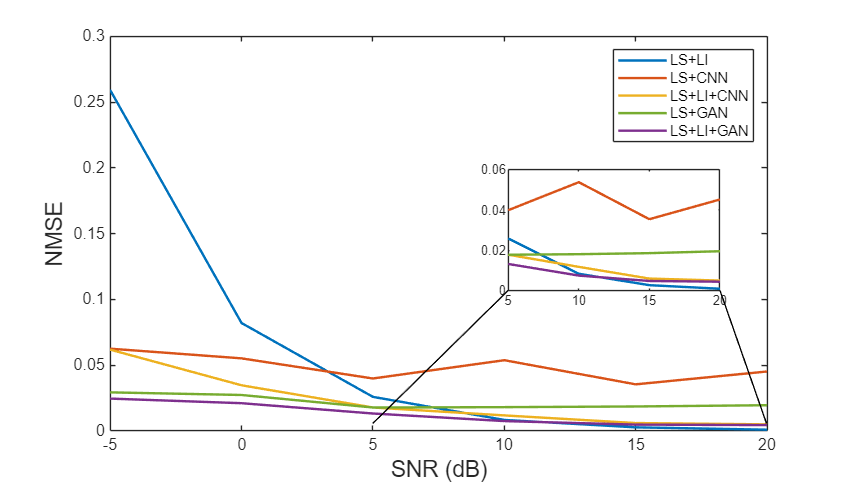

box on;
% Plot the zoomed-in data in the inset
plot(SNR(i_zoom:j_zoom), transfer_GAN.nmse_LS_LI_val(i_zoom:j_zoom), 'DisplayName', 'LS+LI', 'color', cLS_LI,  'LineWidth', lineWidth);

plot(SNR(i_zoom:j_zoom), transfer_CNN.nmse_LS_NN_val(i_zoom:j_zoom), 'DisplayName', 'LS+CNN', 'color', cLS_CNN,  'LineWidth', lineWidth);
plot(SNR(i_zoom:j_zoom), transfer_CNN.nmse_LI_NN_val(i_zoom:j_zoom), 'DisplayName', 'LS+LI+CNN', 'color', cLS_LI_CNN,  'LineWidth', lineWidth);
plot(SNR(i_zoom:j_zoom), transfer_GAN.nmse_LS_NN_val(i_zoom:j_zoom), 'DisplayName', 'LS+GAN', 'color', cLS_GAN,  'LineWidth', lineWidth);
plot(SNR(i_zoom:j_zoom), transfer_GAN.nmse_LI_NN_val(i_zoom:j_zoom), 'DisplayName', 'LS+LI+GAN', 'color', cLS_LI_GAN,  'LineWidth', lineWidth);
annotation('line', [0.44, 0.6], [0.125, 0.4], 'LineWidth', 0.3);
annotation('line', [0.85, 0.905], [0.4, 0.125], 'LineWidth', 0.3);

% title('Performance of approaches in target domain with transfer learning')

infer_GAN = load('../inference/Pix2Pix/v2_/NMSE.mat');
infer_CNN_0_30 = load('../inference/v5_fig/NMSE5_2.mat');
infer_CNN_25_5 = load('../inference/v6_/NMSE.mat');
infer_CNN.nmse_LI_NN = [infer_CNN_25_5.nmse_LI_NN, infer_CNN_0_30.nmse_LI_NN];
infer_CNN.nmse_LS_NN = [infer_CNN_25_5.nmse_LS_NN, infer_CNN_0_30.nmse_LS_NN];

figure;
set(gcf, 'Position', figure_size); % Set the figure size
plot(SNR(i:j), infer_GAN.nmse_LS_LI(i:j), 'DisplayName', 'LS+LI',  'color', cLS_LI,  'LineWidth', lineWidth);
hold

Current plot held


plot(SNR(i:j), infer_CNN.nmse_LS_NN(i:j), 'DisplayName', 'LS+CNN', 'color', cLS_CNN,  'LineWidth', lineWidth);
plot(SNR(i:j), infer_CNN.nmse_LI_NN(i:j), 'DisplayName', 'LS+LI+CNN', 'color', cLS_LI_CNN,  'LineWidth', lineWidth);
plot(SNR(i:j), infer_GAN.nmse_LS_GAN(i:j), 'DisplayName', 'LS+GAN', 'color', cLS_GAN,  'LineWidth', lineWidth);
plot(SNR(i:j), infer_GAN.nmse_LI_GAN(i:j), 'DisplayName', 'LS+LI+GAN', 'color', cLS_LI_GAN, 'LineWidth', lineWidth);
xticks(SNR(i:j));
legend;
xlabel('SNR (dB)', fontsize=label_fontSize);
ylabel('NMSE', fontsize=label_fontSize);

axes('Position', [0.6, 0.4, 0.25, 0.25]);
x_zoom = SNR(i_zoom:j_zoom);

hold;

Current plot held


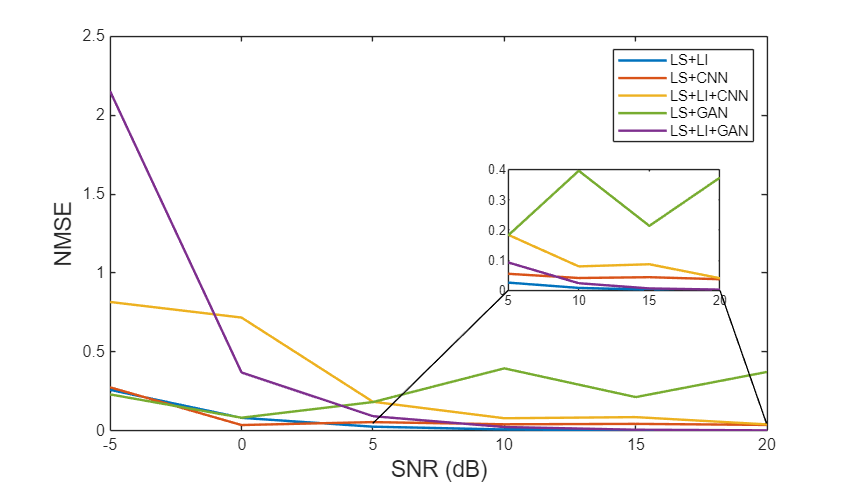

box on;
% Plot the zoomed-in data in the inset
plot(SNR(i_zoom:j_zoom), transfer_GAN.nmse_LS_LI_val(i_zoom:j_zoom), 'DisplayName', 'LS+LI', 'color', cLS_LI,  'LineWidth', lineWidth);

plot(SNR(i_zoom:j_zoom), infer_CNN.nmse_LS_NN(i_zoom:j_zoom), 'DisplayName', 'LS+CNN', 'color', cLS_CNN,  'LineWidth', lineWidth);
plot(SNR(i_zoom:j_zoom), infer_CNN.nmse_LI_NN(i_zoom:j_zoom), 'DisplayName', 'LS+LI+CNN', 'color', cLS_LI_CNN,  'LineWidth', lineWidth);
plot(SNR(i_zoom:j_zoom), infer_GAN.nmse_LS_GAN(i_zoom:j_zoom), 'DisplayName', 'LS+GAN', 'color', cLS_GAN,  'LineWidth', lineWidth);
plot(SNR(i_zoom:j_zoom), infer_GAN.nmse_LI_GAN(i_zoom:j_zoom), 'DisplayName', 'LS+LI+GAN', 'color', cLS_LI_GAN,  'LineWidth', lineWidth);
annotation('line', [0.44, 0.6], [0.125, 0.4], 'LineWidth', 0.3);
annotation('line', [0.85, 0.905], [0.4, 0.125], 'LineWidth', 0.3);

With Transfer learning

figure;
set(gcf, 'Position', figure_size); % Set the figure size
box on;
hold

Current plot held


plot(SNR(i:j), transfer_GAN.nmse_LS_LI_val(i:j), 'DisplayName', 'LS+LI',  'color', cLS_LI,  'LineWidth', lineWidth);
plot(SNR(i:j), infer_CNN.nmse_LI_NN(i:j), 'DisplayName', 'LS+LI+CNN, w/o TF', 'LineStyle', '--', 'color', cLS_LI_CNN, 'LineWidth', lineWidth);
plot(SNR(i:j), transfer_CNN.nmse_LI_NN_val(i:j), 'DisplayName', 'LS+LI+CNN, with TF', 'color', cLS_LI_CNN, 'LineWidth', lineWidth);
plot(SNR(i:j), infer_GAN.nmse_LI_GAN(i:j), 'DisplayName', 'LS+LI+GAN, w/o TF', 'LineStyle', '--', 'color', cLS_LI_GAN, 'LineWidth', lineWidth);
plot(SNR(i:j), transfer_GAN.nmse_LI_NN_val(i:j), 'DisplayName', 'LS+LI+GAN, with TF', 'color', cLS_LI_GAN, 'LineWidth', lineWidth);
xticks(SNR(i:j));
legend;
xlabel('SNR (dB)', fontsize=label_fontSize);
ylabel('NMSE', fontsize=label_fontSize);

i_zoom1 = 6;
axes('Position', [0.6, 0.4, 0.25, 0.25]);
x_zoom = SNR(i_zoom:j_zoom);

hold;

Current plot held


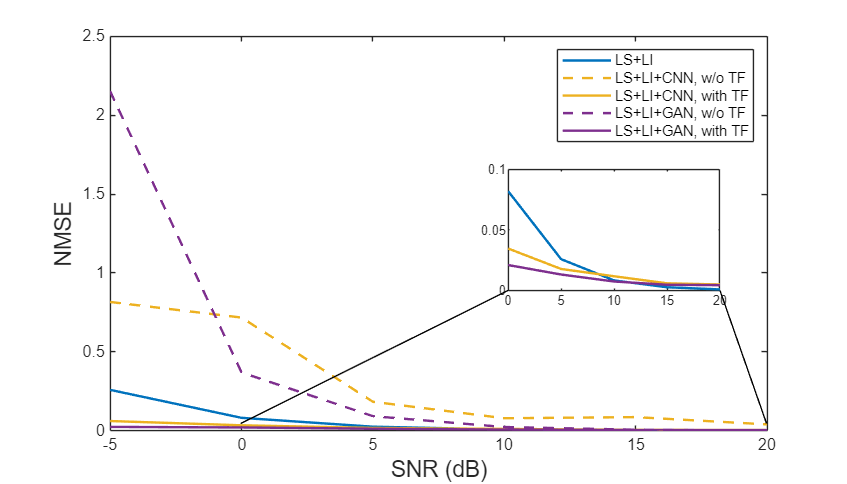

box on;
% Plot the zoomed-in data in the inset
plot(SNR(i_zoom1:j_zoom), transfer_GAN.nmse_LS_LI_val(i_zoom1:j_zoom), 'DisplayName', 'LS+LI',  'color', cLS_LI,  'LineWidth', lineWidth);
% plot(SNR(i_zoom:j_zoom), infer_CNN.nmse_LI_NN(i_zoom:j_zoom), 'DisplayName', 'LS+LI+CNN, w/o TF', 'LineStyle', '--', 'color', cLS_LI_CNN, 'LineWidth', lineWidth);
plot(SNR(i_zoom1:j_zoom), transfer_CNN.nmse_LI_NN_val(i_zoom1:j_zoom), 'DisplayName', 'LS+LI+CNN, with TF', 'color', cLS_LI_CNN, 'LineWidth', lineWidth);
% plot(SNR(i_zoom:j_zoom), infer_GAN.nmse_LI_GAN(i_zoom:j_zoom), 'DisplayName', 'LS+LI+GAN, w/o TF', 'LineStyle', '--', 'color', cLS_LI_GAN, 'LineWidth', lineWidth);
plot(SNR(i_zoom1:j_zoom), transfer_GAN.nmse_LI_NN_val(i_zoom1:j_zoom), 'DisplayName', 'LS+LI+GAN, with TF', 'color', cLS_LI_GAN, 'LineWidth', lineWidth);
annotation('line', [0.284, 0.6], [0.125, 0.4], 'LineWidth', 0.3);
annotation('line', [0.85, 0.905], [0.4, 0.125], 'LineWidth', 0.3);

______________________________________-----------------------------------------------------------------_________________________________

figure;
set(gcf, 'Position', figure_size); % Set the figure size
% set(gca, 'YScale', 'log')
box on;
hold

Current plot held


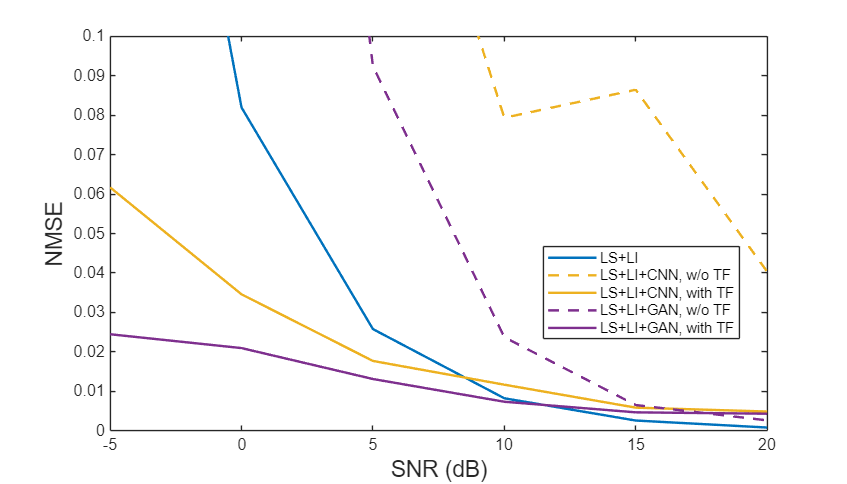


plot(SNR(i:j), transfer_GAN.nmse_LS_LI_val(i:j), 'DisplayName', 'LS+LI',  'color', cLS_LI,  'LineWidth', lineWidth);
plot(SNR(i:j), infer_CNN.nmse_LI_NN(i:j), 'DisplayName', 'LS+LI+CNN, w/o TF', 'LineStyle', '--', 'color', cLS_LI_CNN, 'LineWidth', lineWidth);
plot(SNR(i:j), transfer_CNN.nmse_LI_NN_val(i:j), 'DisplayName', 'LS+LI+CNN, with TF', 'color', cLS_LI_CNN, 'LineWidth', lineWidth);
plot(SNR(i:j), infer_GAN.nmse_LI_GAN(i:j), 'DisplayName', 'LS+LI+GAN, w/o TF', 'LineStyle', '--', 'color', cLS_LI_GAN, 'LineWidth', lineWidth);
plot(SNR(i:j), transfer_GAN.nmse_LI_NN_val(i:j), 'DisplayName', 'LS+LI+GAN, with TF', 'color', cLS_LI_GAN, 'LineWidth', lineWidth);
xticks(SNR(i:j));
% xlim([SNR(i) SNR(j)])  % Set x-axis limits  
ylim([0 0.1])  % Set y-axis limits  
legend;
xlabel('SNR (dB)', fontsize=label_fontSize);
ylabel('NMSE', fontsize=label_fontSize);

figure;
set(gcf, 'Position', figure_size); % Set the figure size
% set(gca, 'YScale', 'log')
box on;
hold

Current plot held


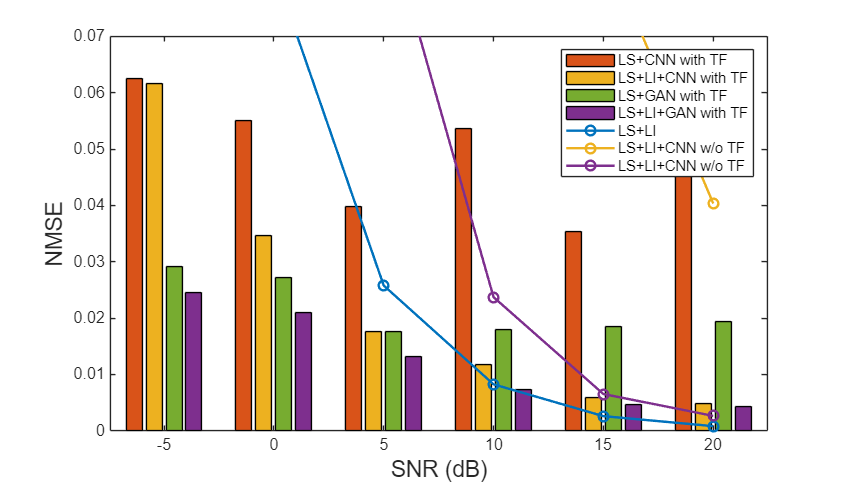

x = SNR(i:j); 
% bar plot for transfer models 
y1 = transfer_CNN.nmse_LS_NN_val(i:j);  % transfer LS CNN
y2 = transfer_CNN.nmse_LI_NN_val(i:j);  % transfer LS LI CNN
y3 = transfer_GAN.nmse_LS_NN_val(i:j);  % transfer LS GAN
y4 = transfer_GAN.nmse_LI_NN_val(i:j);  % transfer LS LI GAN

% Combine y-values into a matrix for grouped bars
Y = [y1; y2; y3; y4]';

% Plot as a grouped bar chart
b = bar(x, Y, 'grouped');
b(1).FaceColor = cLS_CNN; 
b(2).FaceColor = cLS_LI_CNN; 
b(3).FaceColor = cLS_GAN; 
b(4).FaceColor = cLS_LI_GAN;

plot(SNR(i:j), transfer_GAN.nmse_LS_LI_val(i:j), 'DisplayName', 'LS+LI',  'color', cLS_LI,  'LineWidth', lineWidth, 'Marker','o');
plot(SNR(i:j), infer_CNN.nmse_LI_NN(i:j), 'DisplayName', 'LS+LI+CNN, w/o TF', 'color', cLS_LI_CNN, 'LineWidth', lineWidth, 'Marker','o');
plot(SNR(i:j), infer_GAN.nmse_LI_GAN(i:j), 'DisplayName', 'LS+LI+GAN, w/o TF', 'color', cLS_LI_GAN, 'LineWidth', lineWidth, 'Marker','o');
xticks(SNR(i:j));

% Set labels
ylim([0 0.07])  % Set y-axis limits 
xlabel('SNR (dB)', fontsize=label_fontSize);
ylabel('NMSE', fontsize=label_fontSize);
legend({'LS+CNN with TF', 'LS+LI+CNN with TF', 'LS+GAN with TF', 'LS+LI+GAN with TF', 'LS+LI', 'LS+LI+CNN w/o TF', 'LS+LI+CNN w/o TF'})

i=5;
j=10;
i_zoom = 7;
j_zoom = 10;

SNR=-25:5:30;
figure_size = [100, 100, 700, 400]; % [left, bottom, width, height]
lineWidth=1.5;
label_fontSize = 14;
% specify color
cLS_LI = "#0072BD";
cLS_CNN = "#D95319" ;
cLS_LI_CNN = "#EDB120";
cLS_GAN = "#77AC30"; 
cLS_LI_GAN =  "#7E2F8E";

# In source domain

data_GAN = load('../model/static/GAN/BS16/3500_3516/ver11_/nmse.mat');
data_CNN_0_30 = load('../figure/static/CNN/BS16/3500_3516/ver14_/NMSE.mat');
data_CNN_25_5 = load('../figure/static/CNN/BS16/3500_3516/ver27_/NMSE.mat');
data_CNN.nmse_LI_NN_val = [data_CNN_25_5.nmse_LI_NN_val, data_CNN_0_30.nmse_LI_NN_val];
data_CNN.nmse_LS_NN_val = [data_CNN_25_5.nmse_LS_NN_val, data_CNN_0_30.nmse_LS_NN_val];

figure;
set(gcf, 'Position', figure_size); % Set the figure size
plot(SNR(i:j), data_GAN.nmse_LS_LI_val(i:j), 'DisplayName', 'LS+LI', 'color', cLS_LI,  'LineWidth', lineWidth);
hold;
plot(SNR(i:j), data_CNN.nmse_LS_NN_val(i:j), 'DisplayName', 'LS+CNN', 'color', cLS_CNN,  'LineWidth', lineWidth);
plot(SNR(i:j), data_CNN.nmse_LI_NN_val(i:j), 'DisplayName', 'LS+LI+CNN', 'color', cLS_LI_CNN,  'LineWidth', lineWidth);
plot(SNR(i:j), data_GAN.nmse_LS_GAN_val(i:j), 'DisplayName', 'LS+GAN', 'color', cLS_GAN,  'LineWidth', lineWidth);
plot(SNR(i:j), data_GAN.nmse_LI_GAN_val(i:j), 'DisplayName', 'LS+LI+GAN', 'color', cLS_LI_GAN,  'LineWidth', lineWidth);
xticks(SNR(i:j));
legend;
xlabel('SNR (dB)', fontsize=label_fontSize);
ylabel('NMSE', fontsize=label_fontSize);


axes('Position', [0.6, 0.4, 0.25, 0.25]);
x_zoom = SNR(i_zoom:j_zoom);

hold;
box on;
% Plot the zoomed-in data in the inset
plot(SNR(i_zoom:j_zoom), data_GAN.nmse_LS_LI_val(i_zoom:j_zoom), 'DisplayName', 'LS+LI', 'color', cLS_LI,  'LineWidth', lineWidth);

plot(SNR(i_zoom:j_zoom), data_CNN.nmse_LS_NN_val(i_zoom:j_zoom), 'DisplayName', 'LS+CNN', 'color', cLS_CNN,  'LineWidth', lineWidth);
plot(SNR(i_zoom:j_zoom), data_CNN.nmse_LI_NN_val(i_zoom:j_zoom), 'DisplayName', 'LS+LI+CNN', 'color', cLS_LI_CNN,  'LineWidth', lineWidth);
plot(SNR(i_zoom:j_zoom), data_GAN.nmse_LS_GAN_val(i_zoom:j_zoom), 'DisplayName', 'LS+GAN', 'color', cLS_GAN,  'LineWidth', lineWidth);
plot(SNR(i_zoom:j_zoom), data_GAN.nmse_LI_GAN_val(i_zoom:j_zoom), 'DisplayName', 'LS+LI+GAN', 'color', cLS_LI_GAN,  'LineWidth', lineWidth);
annotation('line', [0.44, 0.6], [0.125, 0.4], 'LineWidth', 0.3);
annotation('line', [0.85, 0.905], [0.4, 0.125], 'LineWidth', 0.3);

% xlim([4 6]);  % Set x-axis limits for zoom
% ylim([min([y1_zoom, y2_zoom]) max([y1_zoom, y2_zoom])]);  % Set y-axis limits for zoom


% title('Performance of approaches in source domain')

# In target domain

Without Transfer learning

transfer_GAN = load('../transfer/transferd_model/static/GAN/ver9_/NMSE.mat');
transfer_CNN_0_30 = load('../transfer/transferd_model/static/CNN/ver10_/NMSE.mat');
transfer_CNN_25_5 = load('../transfer/transferd_model/static/CNN/ver11_/NMSE.mat');
transfer_CNN.nmse_LI_NN_val = [transfer_CNN_25_5.nmse_LI_NN_val, transfer_CNN_0_30.nmse_LI_NN_val];
transfer_CNN.nmse_LS_NN_val = [transfer_CNN_25_5.nmse_LS_NN_val, transfer_CNN_0_30.nmse_LS_NN_val];

figure;
set(gcf, 'Position', figure_size); % Set the figure size
plot(SNR(i:j), transfer_GAN.nmse_LS_LI_val(i:j), 'DisplayName', 'LS+LI',  'color', cLS_LI,  'LineWidth', lineWidth);
hold
plot(SNR(i:j), transfer_CNN.nmse_LS_NN_val(i:j), 'DisplayName', 'LS+CNN', 'color', cLS_CNN,  'LineWidth', lineWidth);
plot(SNR(i:j), transfer_CNN.nmse_LI_NN_val(i:j), 'DisplayName', 'LS+LI+CNN', 'color', cLS_LI_CNN,  'LineWidth', lineWidth);
plot(SNR(i:j), transfer_GAN.nmse_LS_NN_val(i:j), 'DisplayName', 'LS+GAN', 'color', cLS_GAN,  'LineWidth', lineWidth);
plot(SNR(i:j), transfer_GAN.nmse_LI_NN_val(i:j), 'DisplayName', 'LS+LI+GAN', 'color', cLS_LI_GAN, 'LineWidth', lineWidth);
xticks(SNR(i:j));
legend;
xlabel('SNR (dB)', fontsize=label_fontSize);
ylabel('NMSE', fontsize=label_fontSize);


axes('Position', [0.6, 0.4, 0.25, 0.25]);
x_zoom = SNR(i_zoom:j_zoom);

hold;
box on;
% Plot the zoomed-in data in the inset
plot(SNR(i_zoom:j_zoom), transfer_GAN.nmse_LS_LI_val(i_zoom:j_zoom), 'DisplayName', 'LS+LI', 'color', cLS_LI,  'LineWidth', lineWidth);

plot(SNR(i_zoom:j_zoom), transfer_CNN.nmse_LS_NN_val(i_zoom:j_zoom), 'DisplayName', 'LS+CNN', 'color', cLS_CNN,  'LineWidth', lineWidth);
plot(SNR(i_zoom:j_zoom), transfer_CNN.nmse_LI_NN_val(i_zoom:j_zoom), 'DisplayName', 'LS+LI+CNN', 'color', cLS_LI_CNN,  'LineWidth', lineWidth);
plot(SNR(i_zoom:j_zoom), transfer_GAN.nmse_LS_NN_val(i_zoom:j_zoom), 'DisplayName', 'LS+GAN', 'color', cLS_GAN,  'LineWidth', lineWidth);
plot(SNR(i_zoom:j_zoom), transfer_GAN.nmse_LI_NN_val(i_zoom:j_zoom), 'DisplayName', 'LS+LI+GAN', 'color', cLS_LI_GAN,  'LineWidth', lineWidth);
annotation('line', [0.44, 0.6], [0.125, 0.4], 'LineWidth', 0.3);
annotation('line', [0.85, 0.905], [0.4, 0.125], 'LineWidth', 0.3);
% title('Performance of approaches in target domain with transfer learning')

infer_GAN = load('../inference/Pix2Pix/v2_/NMSE.mat');
infer_CNN_0_30 = load('../inference/v5_fig/NMSE5_2.mat');
infer_CNN_25_5 = load('../inference/v6_/NMSE.mat');
infer_CNN.nmse_LI_NN = [infer_CNN_25_5.nmse_LI_NN, infer_CNN_0_30.nmse_LI_NN];
infer_CNN.nmse_LS_NN = [infer_CNN_25_5.nmse_LS_NN, infer_CNN_0_30.nmse_LS_NN];

figure;
set(gcf, 'Position', figure_size); % Set the figure size
plot(SNR(i:j), infer_GAN.nmse_LS_LI(i:j), 'DisplayName', 'LS+LI',  'color', cLS_LI,  'LineWidth', lineWidth);
hold
plot(SNR(i:j), infer_CNN.nmse_LS_NN(i:j), 'DisplayName', 'LS+CNN', 'color', cLS_CNN,  'LineWidth', lineWidth);
plot(SNR(i:j), infer_CNN.nmse_LI_NN(i:j), 'DisplayName', 'LS+LI+CNN', 'color', cLS_LI_CNN,  'LineWidth', lineWidth);
plot(SNR(i:j), infer_GAN.nmse_LS_GAN(i:j), 'DisplayName', 'LS+GAN', 'color', cLS_GAN,  'LineWidth', lineWidth);
plot(SNR(i:j), infer_GAN.nmse_LI_GAN(i:j), 'DisplayName', 'LS+LI+GAN', 'color', cLS_LI_GAN, 'LineWidth', lineWidth);
xticks(SNR(i:j));
legend;
xlabel('SNR (dB)', fontsize=label_fontSize);
ylabel('NMSE', fontsize=label_fontSize);

axes('Position', [0.6, 0.4, 0.25, 0.25]);
x_zoom = SNR(i_zoom:j_zoom);

hold;
box on;
% Plot the zoomed-in data in the inset
plot(SNR(i_zoom:j_zoom), transfer_GAN.nmse_LS_LI_val(i_zoom:j_zoom), 'DisplayName', 'LS+LI', 'color', cLS_LI,  'LineWidth', lineWidth);

plot(SNR(i_zoom:j_zoom), infer_CNN.nmse_LS_NN(i_zoom:j_zoom), 'DisplayName', 'LS+CNN', 'color', cLS_CNN,  'LineWidth', lineWidth);
plot(SNR(i_zoom:j_zoom), infer_CNN.nmse_LI_NN(i_zoom:j_zoom), 'DisplayName', 'LS+LI+CNN', 'color', cLS_LI_CNN,  'LineWidth', lineWidth);
plot(SNR(i_zoom:j_zoom), infer_GAN.nmse_LS_GAN(i_zoom:j_zoom), 'DisplayName', 'LS+GAN', 'color', cLS_GAN,  'LineWidth', lineWidth);
plot(SNR(i_zoom:j_zoom), infer_GAN.nmse_LI_GAN(i_zoom:j_zoom), 'DisplayName', 'LS+LI+GAN', 'color', cLS_LI_GAN,  'LineWidth', lineWidth);
annotation('line', [0.44, 0.6], [0.125, 0.4], 'LineWidth', 0.3);
annotation('line', [0.85, 0.905], [0.4, 0.125], 'LineWidth', 0.3);


With Transfer learning

figure;
set(gcf, 'Position', figure_size); % Set the figure size
box on;
hold
plot(SNR(i:j), transfer_GAN.nmse_LS_LI_val(i:j), 'DisplayName', 'LS+LI',  'color', cLS_LI,  'LineWidth', lineWidth);
plot(SNR(i:j), infer_CNN.nmse_LI_NN(i:j), 'DisplayName', 'LS+LI+CNN, w/o TF', 'LineStyle', '--', 'color', cLS_LI_CNN, 'LineWidth', lineWidth);
plot(SNR(i:j), transfer_CNN.nmse_LI_NN_val(i:j), 'DisplayName', 'LS+LI+CNN, with TF', 'color', cLS_LI_CNN, 'LineWidth', lineWidth);
plot(SNR(i:j), infer_GAN.nmse_LI_GAN(i:j), 'DisplayName', 'LS+LI+GAN, w/o TF', 'LineStyle', '--', 'color', cLS_LI_GAN, 'LineWidth', lineWidth);
plot(SNR(i:j), transfer_GAN.nmse_LI_NN_val(i:j), 'DisplayName', 'LS+LI+GAN, with TF', 'color', cLS_LI_GAN, 'LineWidth', lineWidth);
xticks(SNR(i:j));
legend;
xlabel('SNR (dB)', fontsize=label_fontSize);
ylabel('NMSE', fontsize=label_fontSize);

i_zoom1 = 6;
axes('Position', [0.6, 0.4, 0.25, 0.25]);
x_zoom = SNR(i_zoom:j_zoom);

hold;
box on;
% Plot the zoomed-in data in the inset
plot(SNR(i_zoom1:j_zoom), transfer_GAN.nmse_LS_LI_val(i_zoom1:j_zoom), 'DisplayName', 'LS+LI',  'color', cLS_LI,  'LineWidth', lineWidth);
% plot(SNR(i_zoom:j_zoom), infer_CNN.nmse_LI_NN(i_zoom:j_zoom), 'DisplayName', 'LS+LI+CNN, w/o TF', 'LineStyle', '--', 'color', cLS_LI_CNN, 'LineWidth', lineWidth);
plot(SNR(i_zoom1:j_zoom), transfer_CNN.nmse_LI_NN_val(i_zoom1:j_zoom), 'DisplayName', 'LS+LI+CNN, with TF', 'color', cLS_LI_CNN, 'LineWidth', lineWidth);
% plot(SNR(i_zoom:j_zoom), infer_GAN.nmse_LI_GAN(i_zoom:j_zoom), 'DisplayName', 'LS+LI+GAN, w/o TF', 'LineStyle', '--', 'color', cLS_LI_GAN, 'LineWidth', lineWidth);
plot(SNR(i_zoom1:j_zoom), transfer_GAN.nmse_LI_NN_val(i_zoom1:j_zoom), 'DisplayName', 'LS+LI+GAN, with TF', 'color', cLS_LI_GAN, 'LineWidth', lineWidth);
annotation('line', [0.284, 0.6], [0.125, 0.4], 'LineWidth', 0.3);
annotation('line', [0.85, 0.905], [0.4, 0.125], 'LineWidth', 0.3);

______________________________________-----------------------------------------------------------------_________________________________

figure;
set(gcf, 'Position', figure_size); % Set the figure size
% set(gca, 'YScale', 'log')
box on;
hold

Current plot held


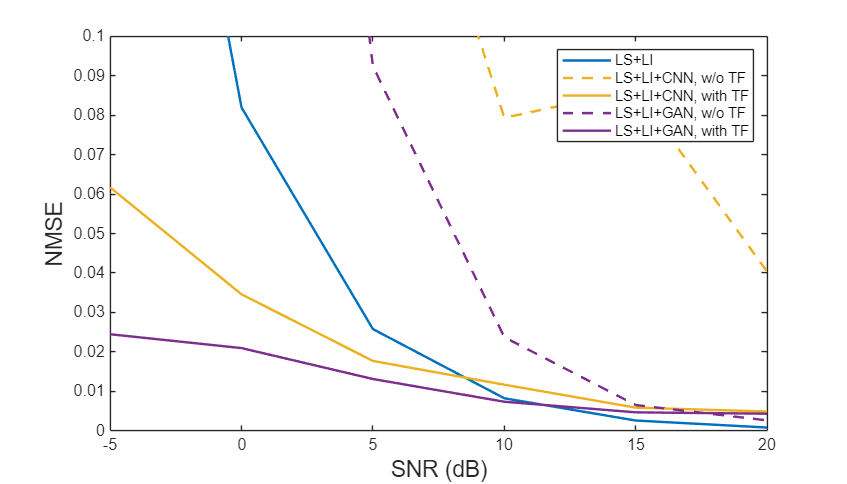


plot(SNR(i:j), transfer_GAN.nmse_LS_LI_val(i:j), 'DisplayName', 'LS+LI',  'color', cLS_LI,  'LineWidth', lineWidth);
plot(SNR(i:j), infer_CNN.nmse_LI_NN(i:j), 'DisplayName', 'LS+LI+CNN, w/o TF', 'LineStyle', '--', 'color', cLS_LI_CNN, 'LineWidth', lineWidth);
plot(SNR(i:j), transfer_CNN.nmse_LI_NN_val(i:j), 'DisplayName', 'LS+LI+CNN, with TF', 'color', cLS_LI_CNN, 'LineWidth', lineWidth);
plot(SNR(i:j), infer_GAN.nmse_LI_GAN(i:j), 'DisplayName', 'LS+LI+GAN, w/o TF', 'LineStyle', '--', 'color', cLS_LI_GAN, 'LineWidth', lineWidth);
plot(SNR(i:j), transfer_GAN.nmse_LI_NN_val(i:j), 'DisplayName', 'LS+LI+GAN, with TF', 'color', cLS_LI_GAN, 'LineWidth', lineWidth);
xticks(SNR(i:j));
% xlim([SNR(i) SNR(j)])  % Set x-axis limits  
ylim([0 0.1])  % Set y-axis limits  
legend;
xlabel('SNR (dB)', fontsize=label_fontSize);
ylabel('NMSE', fontsize=label_fontSize);

figure;
set(gcf, 'Position', figure_size); % Set the figure size
% set(gca, 'YScale', 'log')
box on;
hold

Current plot held


x = SNR(i:j); 
% bar plot for transfer models 
y1 = transfer_CNN.nmse_LS_NN_val(i:j);  % transfer LS CNN
y2 = transfer_CNN.nmse_LI_NN_val(i:j);  % transfer LS LI CNN
y3 = transfer_GAN.nmse_LS_NN_val(i:j);  % transfer LS GAN
y4 = transfer_GAN.nmse_LI_NN_val(i:j);  % transfer LS LI GAN

% Combine y-values into a matrix for grouped bars
Y = [y1; y2; y3; y4]';

% Plot as a grouped bar chart
b = bar(x, Y, 'grouped');
b(1).FaceColor = cLS_CNN; 
b(2).FaceColor = cLS_LI_CNN; 
b(3).FaceColor = cLS_GAN; 
b(4).FaceColor = cLS_LI_GAN;

plot(SNR(i:j), transfer_GAN.nmse_LS_LI_val(i:j), 'DisplayName', 'LS+LI',  'color', cLS_LI,  'LineWidth', lineWidth, 'Marker','o');
plot(SNR(i:j), infer_CNN.nmse_LI_NN(i:j), 'DisplayName', 'LS+LI+CNN, w/o TF', 'color', cLS_LI_CNN, 'LineWidth', lineWidth, 'Marker','o');
plot(SNR(i:j), infer_GAN.nmse_LI_GAN(i:j), 'DisplayName', 'LS+LI+GAN, w/o TF', 'color', cLS_LI_GAN, 'LineWidth', lineWidth, 'Marker','o');
xticks(SNR(i:j));

% Set labels
ylim([0 0.07])  % Set y-axis limits 
xlabel('SNR (dB)', fontsize=label_fontSize);
ylabel('NMSE', fontsize=label_fontSize);
legend({'LS+CNN with TF', 'LS+LI+CNN with TF', 'LS+GAN with TF', 'LS+LI+GAN with TF', 'LS+LI', 'LS+LI+CNN w/o TF', 'LS+LI+CNN w/o TF'})

i=5;
j=10;
i_zoom = 7;
j_zoom = 10;

SNR=-25:5:30;
figure_size = [100, 100, 700, 400]; % [left, bottom, width, height]
lineWidth=1.5;
label_fontSize = 14;
% specify color
cLS_LI = "#0072BD";
cLS_CNN = "#D95319" ;
cLS_LI_CNN = "#EDB120";
cLS_GAN = "#77AC30"; 
cLS_LI_GAN =  "#7E2F8E";

# In source domain

data_GAN = load('../model/static/GAN/BS16/3500_3516/ver11_/nmse.mat');
data_CNN_0_30 = load('../figure/static/CNN/BS16/3500_3516/ver14_/NMSE.mat');
data_CNN_25_5 = load('../figure/static/CNN/BS16/3500_3516/ver27_/NMSE.mat');
data_CNN.nmse_LI_NN_val = [data_CNN_25_5.nmse_LI_NN_val, data_CNN_0_30.nmse_LI_NN_val];
data_CNN.nmse_LS_NN_val = [data_CNN_25_5.nmse_LS_NN_val, data_CNN_0_30.nmse_LS_NN_val];

figure;
set(gcf, 'Position', figure_size); % Set the figure size
plot(SNR(i:j), data_GAN.nmse_LS_LI_val(i:j), 'DisplayName', 'LS+LI', 'color', cLS_LI,  'LineWidth', lineWidth);
hold;
plot(SNR(i:j), data_CNN.nmse_LS_NN_val(i:j), 'DisplayName', 'LS+CNN', 'color', cLS_CNN,  'LineWidth', lineWidth);
plot(SNR(i:j), data_CNN.nmse_LI_NN_val(i:j), 'DisplayName', 'LS+LI+CNN', 'color', cLS_LI_CNN,  'LineWidth', lineWidth);
plot(SNR(i:j), data_GAN.nmse_LS_GAN_val(i:j), 'DisplayName', 'LS+GAN', 'color', cLS_GAN,  'LineWidth', lineWidth);
plot(SNR(i:j), data_GAN.nmse_LI_GAN_val(i:j), 'DisplayName', 'LS+LI+GAN', 'color', cLS_LI_GAN,  'LineWidth', lineWidth);
xticks(SNR(i:j));
legend;
xlabel('SNR (dB)', fontsize=label_fontSize);
ylabel('NMSE', fontsize=label_fontSize);


axes('Position', [0.6, 0.4, 0.25, 0.25]);
x_zoom = SNR(i_zoom:j_zoom);

hold;
box on;
% Plot the zoomed-in data in the inset
plot(SNR(i_zoom:j_zoom), data_GAN.nmse_LS_LI_val(i_zoom:j_zoom), 'DisplayName', 'LS+LI', 'color', cLS_LI,  'LineWidth', lineWidth);

plot(SNR(i_zoom:j_zoom), data_CNN.nmse_LS_NN_val(i_zoom:j_zoom), 'DisplayName', 'LS+CNN', 'color', cLS_CNN,  'LineWidth', lineWidth);
plot(SNR(i_zoom:j_zoom), data_CNN.nmse_LI_NN_val(i_zoom:j_zoom), 'DisplayName', 'LS+LI+CNN', 'color', cLS_LI_CNN,  'LineWidth', lineWidth);
plot(SNR(i_zoom:j_zoom), data_GAN.nmse_LS_GAN_val(i_zoom:j_zoom), 'DisplayName', 'LS+GAN', 'color', cLS_GAN,  'LineWidth', lineWidth);
plot(SNR(i_zoom:j_zoom), data_GAN.nmse_LI_GAN_val(i_zoom:j_zoom), 'DisplayName', 'LS+LI+GAN', 'color', cLS_LI_GAN,  'LineWidth', lineWidth);
annotation('line', [0.44, 0.6], [0.125, 0.4], 'LineWidth', 0.3);
annotation('line', [0.85, 0.905], [0.4, 0.125], 'LineWidth', 0.3);

% xlim([4 6]);  % Set x-axis limits for zoom
% ylim([min([y1_zoom, y2_zoom]) max([y1_zoom, y2_zoom])]);  % Set y-axis limits for zoom


% title('Performance of approaches in source domain')

# In target domain

Without Transfer learning

transfer_GAN = load('../transfer/transferd_model/static/GAN/ver9_/NMSE.mat');
transfer_CNN_0_30 = load('../transfer/transferd_model/static/CNN/ver10_/NMSE.mat');
transfer_CNN_25_5 = load('../transfer/transferd_model/static/CNN/ver11_/NMSE.mat');
transfer_CNN.nmse_LI_NN_val = [transfer_CNN_25_5.nmse_LI_NN_val, transfer_CNN_0_30.nmse_LI_NN_val];
transfer_CNN.nmse_LS_NN_val = [transfer_CNN_25_5.nmse_LS_NN_val, transfer_CNN_0_30.nmse_LS_NN_val];

figure;
set(gcf, 'Position', figure_size); % Set the figure size
plot(SNR(i:j), transfer_GAN.nmse_LS_LI_val(i:j), 'DisplayName', 'LS+LI',  'color', cLS_LI,  'LineWidth', lineWidth);
hold
plot(SNR(i:j), transfer_CNN.nmse_LS_NN_val(i:j), 'DisplayName', 'LS+CNN', 'color', cLS_CNN,  'LineWidth', lineWidth);
plot(SNR(i:j), transfer_CNN.nmse_LI_NN_val(i:j), 'DisplayName', 'LS+LI+CNN', 'color', cLS_LI_CNN,  'LineWidth', lineWidth);
plot(SNR(i:j), transfer_GAN.nmse_LS_NN_val(i:j), 'DisplayName', 'LS+GAN', 'color', cLS_GAN,  'LineWidth', lineWidth);
plot(SNR(i:j), transfer_GAN.nmse_LI_NN_val(i:j), 'DisplayName', 'LS+LI+GAN', 'color', cLS_LI_GAN, 'LineWidth', lineWidth);
xticks(SNR(i:j));
legend;
xlabel('SNR (dB)', fontsize=label_fontSize);
ylabel('NMSE', fontsize=label_fontSize);


axes('Position', [0.6, 0.4, 0.25, 0.25]);
x_zoom = SNR(i_zoom:j_zoom);

hold;
box on;
% Plot the zoomed-in data in the inset
plot(SNR(i_zoom:j_zoom), transfer_GAN.nmse_LS_LI_val(i_zoom:j_zoom), 'DisplayName', 'LS+LI', 'color', cLS_LI,  'LineWidth', lineWidth);

plot(SNR(i_zoom:j_zoom), transfer_CNN.nmse_LS_NN_val(i_zoom:j_zoom), 'DisplayName', 'LS+CNN', 'color', cLS_CNN,  'LineWidth', lineWidth);
plot(SNR(i_zoom:j_zoom), transfer_CNN.nmse_LI_NN_val(i_zoom:j_zoom), 'DisplayName', 'LS+LI+CNN', 'color', cLS_LI_CNN,  'LineWidth', lineWidth);
plot(SNR(i_zoom:j_zoom), transfer_GAN.nmse_LS_NN_val(i_zoom:j_zoom), 'DisplayName', 'LS+GAN', 'color', cLS_GAN,  'LineWidth', lineWidth);
plot(SNR(i_zoom:j_zoom), transfer_GAN.nmse_LI_NN_val(i_zoom:j_zoom), 'DisplayName', 'LS+LI+GAN', 'color', cLS_LI_GAN,  'LineWidth', lineWidth);
annotation('line', [0.44, 0.6], [0.125, 0.4], 'LineWidth', 0.3);
annotation('line', [0.85, 0.905], [0.4, 0.125], 'LineWidth', 0.3);
% title('Performance of approaches in target domain with transfer learning')

infer_GAN = load('../inference/Pix2Pix/v2_/NMSE.mat');
infer_CNN_0_30 = load('../inference/v5_fig/NMSE5_2.mat');
infer_CNN_25_5 = load('../inference/v6_/NMSE.mat');
infer_CNN.nmse_LI_NN = [infer_CNN_25_5.nmse_LI_NN, infer_CNN_0_30.nmse_LI_NN];
infer_CNN.nmse_LS_NN = [infer_CNN_25_5.nmse_LS_NN, infer_CNN_0_30.nmse_LS_NN];

figure;
set(gcf, 'Position', figure_size); % Set the figure size
plot(SNR(i:j), infer_GAN.nmse_LS_LI(i:j), 'DisplayName', 'LS+LI',  'color', cLS_LI,  'LineWidth', lineWidth);
hold
plot(SNR(i:j), infer_CNN.nmse_LS_NN(i:j), 'DisplayName', 'LS+CNN', 'color', cLS_CNN,  'LineWidth', lineWidth);
plot(SNR(i:j), infer_CNN.nmse_LI_NN(i:j), 'DisplayName', 'LS+LI+CNN', 'color', cLS_LI_CNN,  'LineWidth', lineWidth);
plot(SNR(i:j), infer_GAN.nmse_LS_GAN(i:j), 'DisplayName', 'LS+GAN', 'color', cLS_GAN,  'LineWidth', lineWidth);
plot(SNR(i:j), infer_GAN.nmse_LI_GAN(i:j), 'DisplayName', 'LS+LI+GAN', 'color', cLS_LI_GAN, 'LineWidth', lineWidth);
xticks(SNR(i:j));
legend;
xlabel('SNR (dB)', fontsize=label_fontSize);
ylabel('NMSE', fontsize=label_fontSize);

axes('Position', [0.6, 0.4, 0.25, 0.25]);
x_zoom = SNR(i_zoom:j_zoom);

hold;
box on;
% Plot the zoomed-in data in the inset
plot(SNR(i_zoom:j_zoom), transfer_GAN.nmse_LS_LI_val(i_zoom:j_zoom), 'DisplayName', 'LS+LI', 'color', cLS_LI,  'LineWidth', lineWidth);

plot(SNR(i_zoom:j_zoom), infer_CNN.nmse_LS_NN(i_zoom:j_zoom), 'DisplayName', 'LS+CNN', 'color', cLS_CNN,  'LineWidth', lineWidth);
plot(SNR(i_zoom:j_zoom), infer_CNN.nmse_LI_NN(i_zoom:j_zoom), 'DisplayName', 'LS+LI+CNN', 'color', cLS_LI_CNN,  'LineWidth', lineWidth);
plot(SNR(i_zoom:j_zoom), infer_GAN.nmse_LS_GAN(i_zoom:j_zoom), 'DisplayName', 'LS+GAN', 'color', cLS_GAN,  'LineWidth', lineWidth);
plot(SNR(i_zoom:j_zoom), infer_GAN.nmse_LI_GAN(i_zoom:j_zoom), 'DisplayName', 'LS+LI+GAN', 'color', cLS_LI_GAN,  'LineWidth', lineWidth);
annotation('line', [0.44, 0.6], [0.125, 0.4], 'LineWidth', 0.3);
annotation('line', [0.85, 0.905], [0.4, 0.125], 'LineWidth', 0.3);


With Transfer learning

figure;
set(gcf, 'Position', figure_size); % Set the figure size
box on;
hold
plot(SNR(i:j), transfer_GAN.nmse_LS_LI_val(i:j), 'DisplayName', 'LS+LI',  'color', cLS_LI,  'LineWidth', lineWidth);
plot(SNR(i:j), infer_CNN.nmse_LI_NN(i:j), 'DisplayName', 'LS+LI+CNN, w/o TF', 'LineStyle', '--', 'color', cLS_LI_CNN, 'LineWidth', lineWidth);
plot(SNR(i:j), transfer_CNN.nmse_LI_NN_val(i:j), 'DisplayName', 'LS+LI+CNN, with TF', 'color', cLS_LI_CNN, 'LineWidth', lineWidth);
plot(SNR(i:j), infer_GAN.nmse_LI_GAN(i:j), 'DisplayName', 'LS+LI+GAN, w/o TF', 'LineStyle', '--', 'color', cLS_LI_GAN, 'LineWidth', lineWidth);
plot(SNR(i:j), transfer_GAN.nmse_LI_NN_val(i:j), 'DisplayName', 'LS+LI+GAN, with TF', 'color', cLS_LI_GAN, 'LineWidth', lineWidth);
xticks(SNR(i:j));
legend;
xlabel('SNR (dB)', fontsize=label_fontSize);
ylabel('NMSE', fontsize=label_fontSize);

i_zoom1 = 6;
axes('Position', [0.6, 0.4, 0.25, 0.25]);
x_zoom = SNR(i_zoom:j_zoom);

hold;
box on;
% Plot the zoomed-in data in the inset
plot(SNR(i_zoom1:j_zoom), transfer_GAN.nmse_LS_LI_val(i_zoom1:j_zoom), 'DisplayName', 'LS+LI',  'color', cLS_LI,  'LineWidth', lineWidth);
% plot(SNR(i_zoom:j_zoom), infer_CNN.nmse_LI_NN(i_zoom:j_zoom), 'DisplayName', 'LS+LI+CNN, w/o TF', 'LineStyle', '--', 'color', cLS_LI_CNN, 'LineWidth', lineWidth);
plot(SNR(i_zoom1:j_zoom), transfer_CNN.nmse_LI_NN_val(i_zoom1:j_zoom), 'DisplayName', 'LS+LI+CNN, with TF', 'color', cLS_LI_CNN, 'LineWidth', lineWidth);
% plot(SNR(i_zoom:j_zoom), infer_GAN.nmse_LI_GAN(i_zoom:j_zoom), 'DisplayName', 'LS+LI+GAN, w/o TF', 'LineStyle', '--', 'color', cLS_LI_GAN, 'LineWidth', lineWidth);
plot(SNR(i_zoom1:j_zoom), transfer_GAN.nmse_LI_NN_val(i_zoom1:j_zoom), 'DisplayName', 'LS+LI+GAN, with TF', 'color', cLS_LI_GAN, 'LineWidth', lineWidth);
annotation('line', [0.284, 0.6], [0.125, 0.4], 'LineWidth', 0.3);
annotation('line', [0.85, 0.905], [0.4, 0.125], 'LineWidth', 0.3);

______________________________________-----------------------------------------------------------------_________________________________

figure;
set(gcf, 'Position', figure_size); % Set the figure size
% set(gca, 'YScale', 'log')
box on;
hold

plot(SNR(i:j), transfer_GAN.nmse_LS_LI_val(i:j), 'DisplayName', 'LS+LI',  'color', cLS_LI,  'LineWidth', lineWidth);
plot(SNR(i:j), infer_CNN.nmse_LI_NN(i:j), 'DisplayName', 'LS+LI+CNN, w/o TF', 'LineStyle', '--', 'color', cLS_LI_CNN, 'LineWidth', lineWidth);
plot(SNR(i:j), transfer_CNN.nmse_LI_NN_val(i:j), 'DisplayName', 'LS+LI+CNN, with TF', 'color', cLS_LI_CNN, 'LineWidth', lineWidth);
plot(SNR(i:j), infer_GAN.nmse_LI_GAN(i:j), 'DisplayName', 'LS+LI+GAN, w/o TF', 'LineStyle', '--', 'color', cLS_LI_GAN, 'LineWidth', lineWidth);
plot(SNR(i:j), transfer_GAN.nmse_LI_NN_val(i:j), 'DisplayName', 'LS+LI+GAN, with TF', 'color', cLS_LI_GAN, 'LineWidth', lineWidth);
xticks(SNR(i:j));
% xlim([SNR(i) SNR(j)])  % Set x-axis limits  
ylim([0 0.1])  % Set y-axis limits  
legend;
xlabel('SNR (dB)', fontsize=label_fontSize);
ylabel('NMSE', fontsize=label_fontSize);

figure;
set(gcf, 'Position', figure_size); % Set the figure size
% set(gca, 'YScale', 'log')
box on;
hold

Current plot held


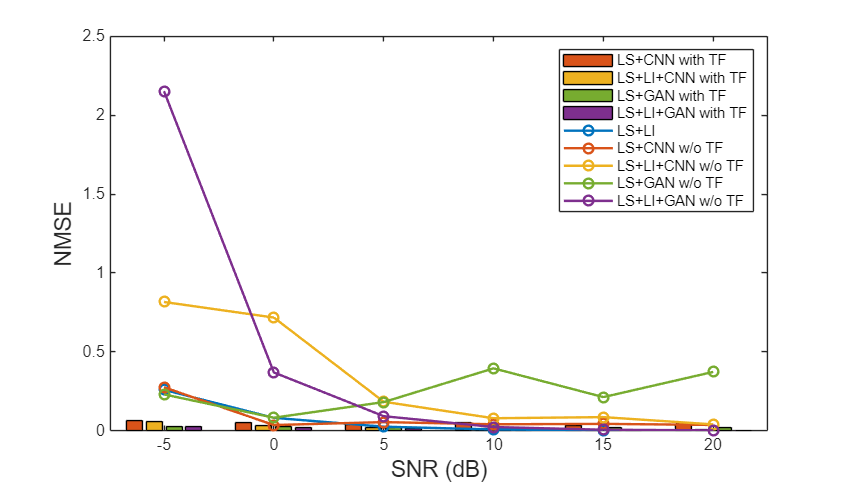

x = SNR(i:j); 
% bar plot for transfer models 
y1 = transfer_CNN.nmse_LS_NN_val(i:j);  % transfer LS CNN
y2 = transfer_CNN.nmse_LI_NN_val(i:j);  % transfer LS LI CNN
y3 = transfer_GAN.nmse_LS_NN_val(i:j);  % transfer LS GAN
y4 = transfer_GAN.nmse_LI_NN_val(i:j);  % transfer LS LI GAN

% Combine y-values into a matrix for grouped bars
Y = [y1; y2; y3; y4]';

% Plot as a grouped bar chart
b = bar(x, Y, 'grouped');
b(1).FaceColor = cLS_CNN; 
b(2).FaceColor = cLS_LI_CNN; 
b(3).FaceColor = cLS_GAN; 
b(4).FaceColor = cLS_LI_GAN;

plot(SNR(i:j), transfer_GAN.nmse_LS_LI_val(i:j), 'DisplayName', 'LS+LI',  'color', cLS_LI,  'LineWidth', lineWidth, 'Marker','o');
plot(SNR(i:j), infer_CNN.nmse_LS_NN(i:j), 'DisplayName', 'LS+CNN, w/o TF', 'color', cLS_CNN, 'LineWidth', lineWidth, 'Marker','o');
plot(SNR(i:j), infer_CNN.nmse_LI_NN(i:j), 'DisplayName', 'LS+LI+CNN, w/o TF', 'color', cLS_LI_CNN, 'LineWidth', lineWidth, 'Marker','o');
plot(SNR(i:j), infer_GAN.nmse_LS_GAN(i:j), 'DisplayName', 'LS+GAN, w/o TF', 'color', cLS_GAN, 'LineWidth', lineWidth, 'Marker','o');
plot(SNR(i:j), infer_GAN.nmse_LI_GAN(i:j), 'DisplayName', 'LS+LI+GAN, w/o TF', 'color', cLS_LI_GAN, 'LineWidth', lineWidth, 'Marker','o');
xticks(SNR(i:j));

% Set labels
% ylim([0 0.08])  % Set y-axis limits 
xlabel('SNR (dB)', fontsize=label_fontSize);
ylabel('NMSE', fontsize=label_fontSize);
legend({'LS+CNN with TF', 'LS+LI+CNN with TF', 'LS+GAN with TF', 'LS+LI+GAN with TF', 'LS+LI', 'LS+CNN w/o TF', 'LS+LI+CNN w/o TF', 'LS+GAN w/o TF', 'LS+LI+GAN w/o TF'})

figure;
set(gcf, 'Position', figure_size); % Set the figure size
% set(gca, 'YScale', 'log')
box on;
hold

Current plot held


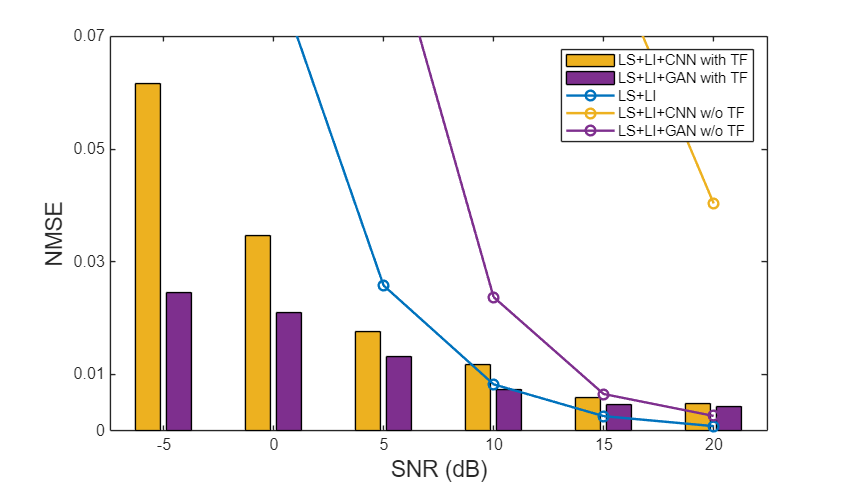

x = SNR(i:j); 
% bar plot for transfer models 
y1 = transfer_CNN.nmse_LI_NN_val(i:j);  % transfer LS LI CNN
y2 = transfer_GAN.nmse_LI_NN_val(i:j);  % transfer LS LI GAN

% Combine y-values into a matrix for grouped bars
Y = [y1; y2]';

% Plot as a grouped bar chart
b = bar(x, Y, 'grouped');
b(1).FaceColor = cLS_LI_CNN; 
b(2).FaceColor = cLS_LI_GAN;

plot(SNR(i:j), transfer_GAN.nmse_LS_LI_val(i:j), 'DisplayName', 'LS+LI',  'color', cLS_LI,  'LineWidth', lineWidth, 'Marker','o');
plot(SNR(i:j), infer_CNN.nmse_LI_NN(i:j), 'DisplayName', 'LS+LI+CNN, w/o TF', 'color', cLS_LI_CNN, 'LineWidth', lineWidth, 'Marker','o');
plot(SNR(i:j), infer_GAN.nmse_LI_GAN(i:j), 'DisplayName', 'LS+LI+GAN, w/o TF', 'color', cLS_LI_GAN, 'LineWidth', lineWidth, 'Marker','o');
xticks(SNR(i:j));
yticks([0 0.01 0.03 0.05 0.07]);

% Set labels
ylim([0 0.07])  % Set y-axis limits 
xlabel('SNR (dB)', fontsize=label_fontSize);
ylabel('NMSE', fontsize=label_fontSize);
legend({'LS+LI+CNN with TF', 'LS+LI+GAN with TF', 'LS+LI', 'LS+LI+CNN w/o TF', 'LS+LI+GAN w/o TF'})